# Example 5.10: Hougen-Watson Models

Note: this script reproduces Example 5.10 (Section 5.3) of **Statistics for Chemical Engineers**: nonlinear estimation of a Hougen-Watson rate model. Victor Z UW-Madison, 2019 estimation for Hougen-Watson equation [https://www.mathworks.com/help/stats/rsmdemo.html](https://www.mathworks.com/help/stats/rsmdemo.html)

clc; clear all; close all hidden; format short e;

% S = load('reaction');
% X = S.reactants % experimental reactant concentrations
% y = S.rate % experimental reaction rates
% beta = S.beta % guess for parameters
%data=[X,y];
%save 'Data/hougenwatson.dat' data -ascii

data=load('Data/hougenwatson.dat');
X=data(:,1:3); %partial pressures
y=data(:,4);   % reaction rate

## Data and initial guess

best guess for parameters

beta = [1.0000e+00
        5.0000e-02
        2.0000e-02
        1.0000e-01
        2.0000e+00];

[n,m]=size(X);

## The SSE function

span SSE function using one parameter

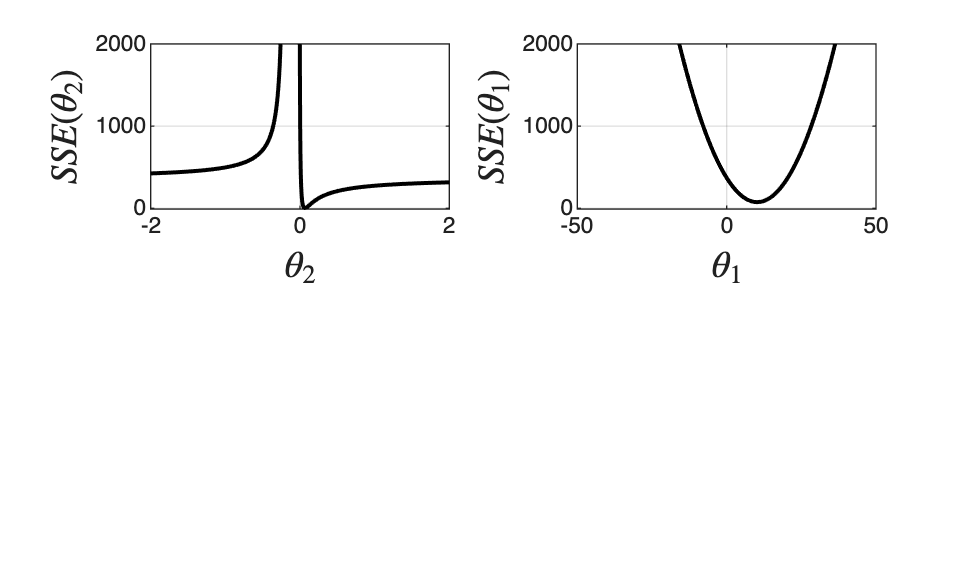

nmesh = 1000;
bv = linspace(-2,2,nmesh); 
betav=beta;
for j=1:nmesh
    betav(2)=bv(j);
    for i=1:n
     yhat(i)=myf(betav,X(i,:));
     e(i)=0.5*(y(i)-yhat(i))^2;
    end
    SS(j)=sum(e);
end

figure(1)
subplot(2,2,1)
plot(bv,SS,'black','LineWidth',1.5)
grid on
xlabel('$\theta_2$','Interpreter','latex','FontSize',14)
ylabel('$SSE(\theta_2)$','Interpreter','latex','FontSize',14)
axis([-2 2, -10, 2000])

% span another param
bv = linspace(-50,50,nmesh); 
for j=1:nmesh
    betav(1)=bv(j);
    for i=1:n
     yhat(i)=myf(betav,X(i,:));
     e(i)=0.5*(y(i)-yhat(i))^2;
    end
    SS(j)=sum(e);
end

figure(1)
subplot(2,2,2)
plot(bv,SS,'black','LineWidth',1.5)
grid on
xlabel('$\theta_1$','Interpreter','latex','FontSize',14)
ylabel('$SSE(\theta_1)$','Interpreter','latex','FontSize',14)
axis([-50, 50, -10, 2000])
print -depsc ch5_hougen_span.eps

## Estimation with a good initial guess

do estimation with good initial guess

beta=ones(5,1);
myfun = 'y~(b1*x2-x3/b5)/(1+b2*x1+b3*x2+b4*x3)';
opts = statset('Display','iter','TolFun',1e-10);
nlm = fitnlm(X,y,myfun,beta,'Options',opts)

 
                                     Norm of         Norm of
   Iteration             SSE        Gradient           Step 
  -----------------------------------------------------------
           0         670.124
           1         586.805         76.9967         1.48272
           2         550.616         219.185        0.179495
           3          522.97         300.889       0.0988136
           4         502.414         372.003       0.0594046
           5         389.634         354.919        0.185653
           6         251.419         197.594        0.539049
           7         209.216         475.637        0.227271
           8         168.098         369.024        0.205188
           9         28.7406         238.861        0.677809
          10         1.05491         184.163        0.383616
          11        0.324806        0.642909       0.0619546
          12        0.324114        0.200524       0.0427728
          13        0.323524        0.247233       0.

nlm = Nonlinear regression model:
    y ~ (b1*x2 - x3/b5)/(1 + b2*x1 + b3*x2 + b4*x3)

Estimated Coefficients:
           Estimate         SE          tStat         pValue  
          __________    __________    __________    __________
    b1    1.2526e+00    8.6702e-01    1.4447e+00    1.8654e-01
    b2    6.2776e-02    4.3562e-02    1.4411e+00    1.8753e-01
    b3    4.0048e-02    3.0885e-02    1.2967e+00    2.3089e-01
    b4    1.1242e-01    7.5158e-02    1.4957e+00    1.7309e-01
    b5    1.1914e+00    8.3671e-01    1.4239e+00    1.9230e-01

Number of observations: 13, Error degrees of freedom: 8
Root Mean Squared Error: 0.193
R-Squared: 0.999,  Adjusted R-Squared 0.998
F-statistic vs. zero model: 3.91e+03, p-value = 2.54e-13

coefCI(nlm)

ans =   -7.4676e-01   3.2520e+00
  -3.7677e-02   1.6323e-01
  -3.1173e-02   1.1127e-01
  -6.0899e-02   2.8573e-01
  -7.3809e-01   3.1208e+00


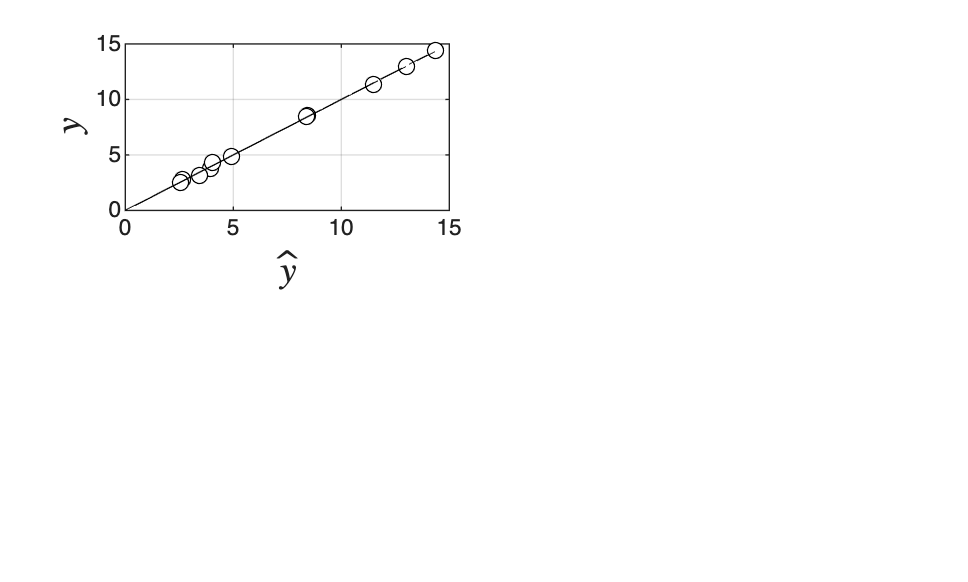

yhat = predict(nlm,X);

figure(2)
subplot(2,2,1)
plot(yhat,y,'blacko','MarkerFaceColor','w')
hold on
plot(y,y,'black--')
xlabel('$\hat{y}$','Interpreter','latex','FontSize',14)
ylabel('$y$','Interpreter','latex','FontSize',14)
grid on
axis([0 15 0 15])

## Estimation with a bad initial guess

do estimation with bad initial guess

beta=ones(5,1)*(-1);
myfun = 'y~(b1*x2-x3/b5)/(1+b2*x1+b3*x2+b4*x3)';
opts = statset('Display','iter','TolFun',1e-10,'MaxIter',200);
nlm2 = fitnlm(X,y,myfun,beta,'Options',opts)

 
                                     Norm of         Norm of
   Iteration             SSE        Gradient           Step 
  -----------------------------------------------------------
           0          669.86
           1         587.007         77.4445         1.46884
           2         550.688         218.858        0.180522
           3         522.964         300.834       0.0990185
           4         502.333         372.189       0.0595764
           5         387.812         350.085        0.188555
           6         254.854         214.971        0.535632
           7         208.675         388.258        0.258739
           8         164.286          374.38        0.206493
           9         19.9352          274.15        0.585002
          10        0.895208          146.28        0.279133
          11         0.47045         4.75633        0.115634
          12        0.466159         1.06943        0.111604
          13        0.462599         1.01451        0

nlm2 = Nonlinear regression model:
    y ~ (b1*x2 - x3/b5)/(1 + b2*x1 + b3*x2 + b4*x3)

Estimated Coefficients:
           Estimate          SE           tStat         pValue  
          ___________    __________    ___________    __________
    b1    -7.3603e+01    3.2333e+03    -2.2764e-02    9.8240e-01
    b2    -3.7020e+00    1.6262e+02    -2.2765e-02    9.8240e-01
    b3    -2.6167e+00    1.1475e+02    -2.2803e-02    9.8237e-01
    b4    -6.3625e+00    2.7969e+02    -2.2749e-02    9.8241e-01
    b5    -2.0033e-02    8.9862e-01    -2.2293e-02    9.8276e-01

Number of observations: 13, Error degrees of freedom: 8
Root Mean Squared Error: 0.219
R-Squared: 0.999,  Adjusted R-Squared 0.998
F-statistic vs. zero model: 3.04e+03, p-value = 6.87e-13

coefCI(nlm2)

ans =   -7.5297e+03   7.3825e+03
  -3.7870e+02   3.7130e+02
  -2.6724e+02   2.6201e+02
  -6.5132e+02   6.3859e+02
  -2.0923e+00   2.0522e+00


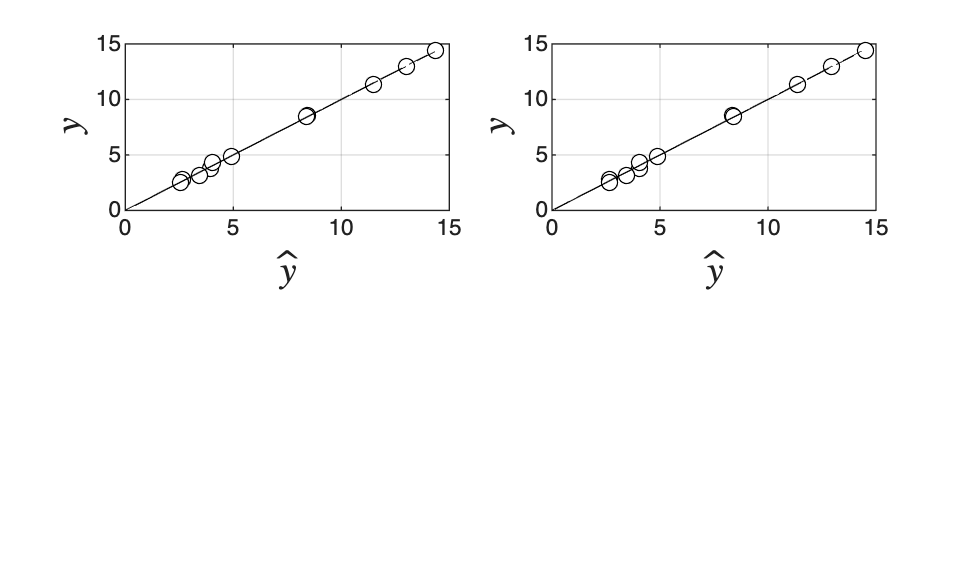

yhat2 = predict(nlm2,X);

figure(2)
subplot(2,2,2)
plot(yhat2,y,'blacko','MarkerFaceColor','w')
hold on
plot(y,y,'black--')
xlabel('$\hat{y}$','Interpreter','latex','FontSize',14)
ylabel('$y$','Interpreter','latex','FontSize',14)
grid on
axis([0 15 0 15])
print -depsc ch5_hougen_fit.eps

## define nonlinear function to fit

function y=myf(b,x)

b1=b(1);
b2=b(2);
b3=b(3);
b4=b(4);
b5=b(5);
x1=x(1);
x2=x(2);
x3=x(3);

y=(b1*x2-x3/b5)/(1+b2*x1+b3*x2+b4*x3);

end

## Note

As in the book, the SSE function is highly nonlinear: a good initial guess helps, but nothing prevents the solver from landing on estimates with no physical meaning.